clc
clear
% Import the data
TTDmatrix = readmatrix("C:\Users\admin\Desktop\Sim3D\TTD.txt");
height = size(TTDmatrix, 1)

height = 7

width = size(TTDmatrix,2)

width = 100000

TTDx = linspace(0,width,width);
%plot(TTDx,1000-TTD)
%% Clear temporary variables
clear opts
TTDx = TTDx(2:end);

% Constants
deltax = 1/100

deltax = 0.0100

deltay = 1/100

deltay = 0.0100

deltaz = 1/100

deltaz = 0.0100

D_3d = (deltax^2 + deltay^2 + deltaz^2) / 6; %Skal justeres med 3d.
r_int = 0.05;
%n = 1000;
n = 1;
V = 1;
N = 2;

% Inverse Laplace Transform using Talbot method
% j = @(t) 4*pi*D_3d*r_int*n * (1 + r_int/(sqrt(pi*D_3d*t)));
% j_func = arrayfun(j,TTDx)
% P_surv = @(t) exp(-j(t));
% P_surv_func = arrayfun(P_surv,TTDx);

J_survival = @(t) (2*pi*D_3d*r_int*n /V) * (t + 2 * r_int * sqrt(t/(pi*D_3d)))

J_survival = function_handle with value:
    @(t)(2*pi*D_3d*r_int*n/V)*(t+2*r_int*sqrt(t/(pi*D_3d)))


J_survival_values = arrayfun(J_survival, TTDx)

J_survival_values =     0.0001    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0014    0.0015    0.0015    0.0015    0.0015    0.0016    0.0016    0.0016    0.0016    0.0017



% P_surv_foreign = @(t) (1-j(t))^N
% P_surv_foreign_func = arrayfun(P_surv_foreign, TTDx)

P_survival_test = (exp(-J_survival_values)).^2

P_survival_test =     0.9997    0.9996    0.9995    0.9994    0.9993    0.9992    0.9991    0.9990    0.9990    0.9989    0.9988    0.9988    0.9987    0.9986    0.9986    0.9985    0.9984    0.9984    0.9983    0.9983    0.9982    0.9981    0.9981    0.9980    0.9980    0.9979    0.9979    0.9978    0.9977    0.9977    0.9976    0.9976    0.9975    0.9975    0.9974    0.9974    0.9973    0.9973    0.9972    0.9972    0.9971    0.9971    0.9970    0.9970    0.9969    0.9969    0.9968    0.9968    0.9967    0.9967


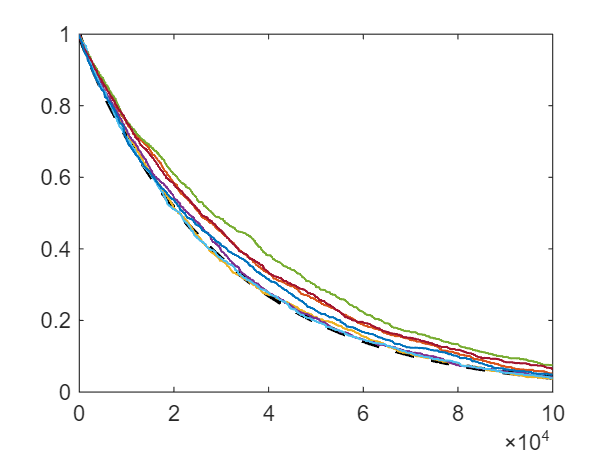


figure();
plot(TTDx,P_survival_test, color='black', LineStyle="--", LineWidth=2);
hold on
for i = 1:height
TTD = TTDmatrix(i,2:end);
plot(TTDx,(1000-TTD)/1000, LineWidth=1);
end
hold off


%Skriv om til periodske randbetingelser.
%Prøv med flere/færre targets.
%Test bindingslogik.

%Mindre targets.
%Test koden
%